%% Alongtrack from OceanDB (array structure)
%eddyPath_track from eddy tracking algorithm
% no eddy field
clear all

## 1. Load extracted tracks along the eddy path

eddy_id='+527413';
filename = strcat(['G:/My Drive/AlongTrack/MyCode/eddy_',eddy_id,'.nc']);
timeo = ncread(filename,'eddy/time')+datenum(1950,01,01); %Initial time is also a free parameter
eddy_time = timeo-min(timeo);

clearvars eddyPath
eddyPath.lat = ncread(filename,'eddy/latitude');
eddyPath.lon = ncread(filename,'eddy/longitude');

%if you want to change the eddyPath to a function handle
eddyPath_fun_t.lon = @(t) interp1(eddy_time, eddyPath.lon, t, 'linear', 'extrap');
eddyPath_fun_t.lat = @(t) interp1(eddy_time, eddyPath.lat, t, 'linear', 'extrap');
% Function to convert any lat/lon to x/y relative to the eddy center at time t
get_eddyPath_xy = @(lat, lon, t) latlon2xy(lat, lon, eddyPath_fun_t.lat(t),eddyPath_fun_t.lon(t));


% %already extracted alongtrack
% at_time = ncread(filename,'alongtrack/time')+datenum(1950,01,01);
% at_lat = ncread(filename,'alongtrack/latitude');
% at_lon = ncread(filename,'alongtrack/longitude');
% at_sla = ncread(filename,'alongtrack/sla_filtered');
% at_tracknumber = ncread(filename,'alongtrack/track');
% 
% %array of all tracks (no need to repeat)
% alongtrackLatLon.t=at_time;
% alongtrackLatLon.lat=at_lat;
% alongtrackLatLon.lon=at_lon;
% alongtrackLatLon.ssh=at_sla;


% other option to get it from Jonathan's nc 3D file.
readdir = 'G:\My Drive\AlongTrack\';
%% Alongtrack from Jonathan (3D matrix [atd, tracknumber, cycle])
JasonAlongTrack.filename = strcat(readdir, 'JasonAlongTrack.nc');
JasonAlongTrack.lat = ncread(JasonAlongTrack.filename, 'lat');
JasonAlongTrack.lon = ncread(JasonAlongTrack.filename, 'lon');
%JML convert time to Matlab's datenum format
JasonAlongTrack.time = ncread(JasonAlongTrack.filename, 'time') + datenum(1950, 1, 1);
%Time is defined as beginning at 4:05 AM on Sept 23, 1992,
JasonAlongTrack.ssh = ncread(JasonAlongTrack.filename, 'sla');
alongtrackLatLon = extractAlongtrackLatLonEddyCenter(JasonAlongTrack,eddyPath,timeo,radius=300); %radius in km

% % if loading jasonalongtrack above takes too long, load the mat file 
current_file_path = matlab.desktop.editor.getActiveFilename;
[current_dir, ~, ~] = fileparts(current_file_path);
load(strcat(current_dir,'\alongtrackLatLon_real.mat'))


## Alongtrack in x,y projection about the eddy center

[x_km, y_km]=get_eddyPath_xy(alongtrackLatLon.lat,alongtrackLatLon.lon,alongtrackLatLon.t-min(alongtrackLatLon.t));
alongtrackXY.x=x_km*1e3;
alongtrackXY.y=y_km*1e3;
%if you want to use eddyPath_fun_t.xe,ye as a function handle
%alongtrack are already adjusted to be eddy centered so xo,yo are zeros
eddyPath_fun_t.xe=@(t) 0*t;
eddyPath_fun_t.ye=@(t) 0*t;

## 3. Plots and Videos of OSSE

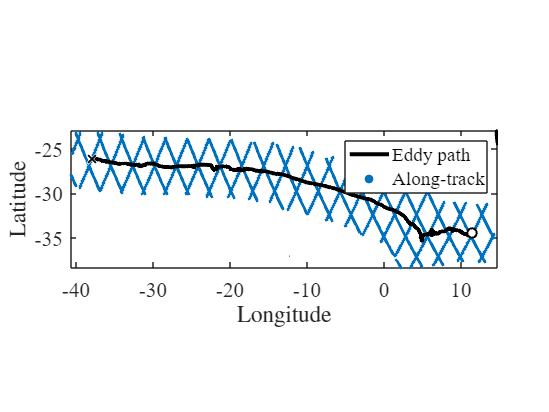

Unrecognized field name "ssh".

Error in plotAlongtrack (line 161)
s = scatter3(plot_x, plot_y, alongtrack.ssh*1e2, 7, alongtrack.ssh*1e2, 'filled', ...

plotAlongtrack(alongtrackLatLon,eddyPath);

clim([-6,25])

%% make video of the propagating eddy
video_name = 'eddy_field_real';
makePropagatingVideo(x,y,eddy_time,eddy_field,video_name)


## 4. Eddy composites from along-track

%eddy center from eddyPath_track, which is from ssh max closed contour centroid
alongtrack.t=alongtrackLatLon.t;
alongtrack.x=alongtrackXY.x;
alongtrack.y=alongtrackXY.y;
alongtrack.ssh=alongtrackLatLon.ssh;

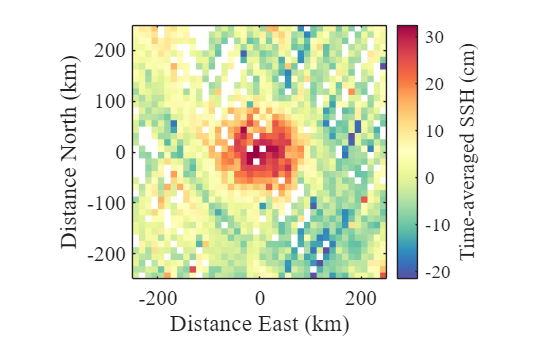

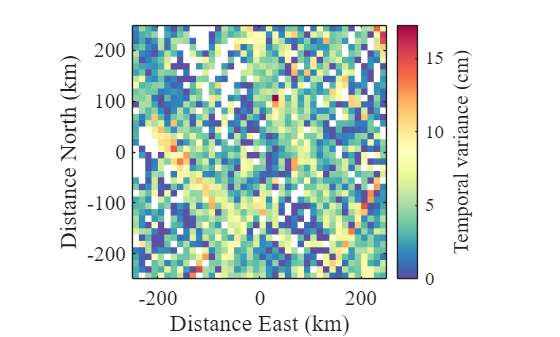

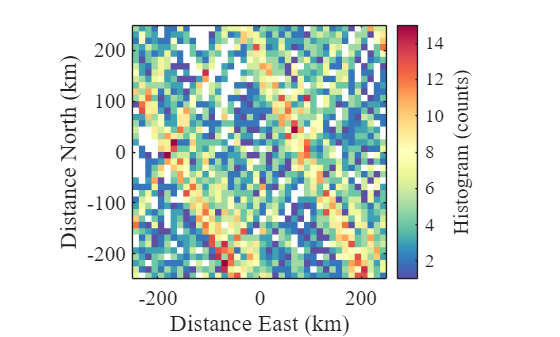

%If you want to narrow the time window
time_window=100:300;%1:length(timeo)-1;
window_idx = find(alongtrack.t-min(alongtrack.t) >= time_window(1) & alongtrackLatLon.t-min(alongtrack.t) <= time_window(end));
alongtrack_window.t=alongtrack.t(window_idx);
alongtrack_window.x=alongtrack.x(window_idx);
alongtrack_window.y=alongtrack.y(window_idx);
alongtrack_window.ssh=alongtrack.ssh(window_idx);
% time-averaged eddy composite
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(alongtrack_window,eddyPath_fun_t);% options: bin_size=12.5*1e3

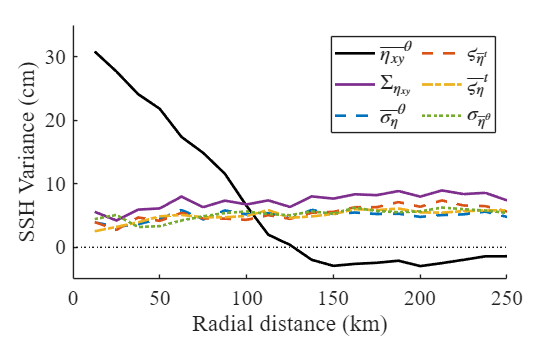

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(alongtrack_window,eddyPath_fun_t);

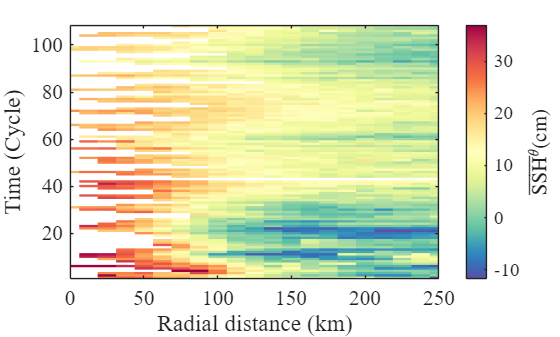

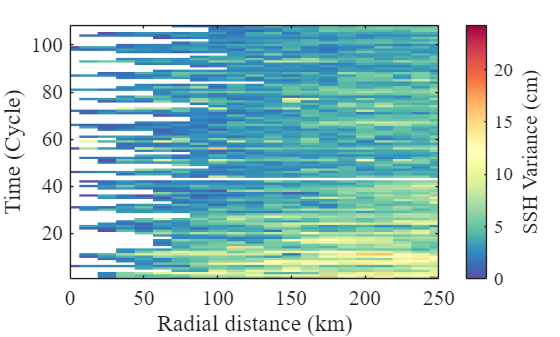

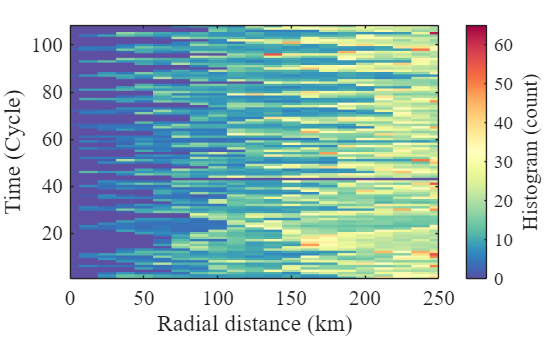

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(alongtrack,eddyPath_fun_t);

## 4. Eddy composites from mapped product

filename = 'D:/UW/aviso_madt.nc';
% filename = 'eddy_-41.nc';
ni=ncinfo(filename);

Error using matlab.internal.imagesci.netcdflib
The NetCDF library encountered an error during execution of 'open' function - 'HDF error (NC_EHDFERR)'.

Error in netcdf.open (line 77)
        [varargout{:}] = matlab.internal.imagesci.netcdflib('open', ...

Error in internal.matlab.imagesci.nc/openToRead (<a href="

mapped_field.time = ncread(filename,'time')+datenum(1950,01,01);
mapped_field.lat = ncread(filename,'latitude'); %ascending
mapped_field.lon = deg180(ncread(filename,'longitude')); % ascending

radius_km=300;%km
bin_size=12.5*1e3;
max_r=(radius_km*1e3/bin_size)*bin_size;
xbin=-max_r:bin_size:max_r;
xmid=(xbin+vshift(xbin,1,1))./2;
xmid=xmid(1:end-1);
ymid=xmid;
[XGrid, YGrid] = ndgrid(xmid, ymid);
clearvars ssh_interp

for n = 1:length(timeo)
    % Find time index closest to current eddy time
    [~, time_idx] = min(abs(mapped_field.time - timeo(n)));

    % Find indices for region around current eddy position
    [~, center_lat] = min(abs(mapped_field.lat - eddyPath.lat(n)));
    [~, center_lon] = min(abs(mapped_field.lon - eddyPath.lon(n)));

    % Calculate the lat-lon box that corresponds to our desired km radius
    [lat_box, lon_box] = xy2latlon([-radius_km, radius_km], [-radius_km, radius_km], eddyPath.lat(n), eddyPath.lon(n));
     
    % Find indices in the grid that match these boundaries
    [~, start_lat] = min(abs(mapped_field.lat - lat_box(1)));
    [~, last_lat] = min(abs(mapped_field.lat - lat_box(2)));
    [~, start_lon] = min(abs(mapped_field.lon - lon_box(1)));
    [~, last_lon] = min(abs(mapped_field.lon - lon_box(2)));
    
    % Handle longitude wrap-around if needed
    if start_lon > last_lon % Crossing the longitude boundary
        % First part: end of longitude array to the end
        start1 = [start_lon, start_lat, time_idx];
        count1 = [length(mapped_field.lon) - start_lon + 1, last_lat - start_lat + 1, 1];
        ssh_part1 = ncread(filename, 'sla', start1, count1); %m
        lon_part1 = mapped_field.lon(start_lon:end);
        
        % Second part: beginning of longitude array to last_lon
        start2 = [1, start_lat, time_idx];
        count2 = [last_lon, last_lat - start_lat + 1, 1];
        ssh_part2 = ncread(filename, 'sla', start2, count2);%m
        lon_part2 = mapped_field.lon(1:last_lon);
        
        % Combine the two parts
        current_ssh = [ssh_part1; ssh_part2];
        current_lon = [lon_part1; lon_part2];
    else
        % Normal case - extraction window within longitude bounds
        start = [start_lon, start_lat, time_idx];
        count = [last_lon - start_lon + 1, last_lat - start_lat + 1, 1];
        current_ssh = ncread(filename, 'sla', start, count);%m
        current_lon = mapped_field.lon(start_lon:last_lon);
    end
    
    current_lat = mapped_field.lat(start_lat:last_lat); %lat doesn't have a if statement bc we don't do eddies that cross the equator
    % Create meshgrid for extracted region
    [lon_grid, lat_grid] = ndgrid(current_lon, current_lat);
    [x_km, y_km]=get_eddyPath_xy(lat_grid,lon_grid,timeo(n)-min(timeo));

    % Interpolate onto a grid
    ssh_interp(:,:,n) = griddata(double(x_km * 1e3), double(y_km * 1e3), current_ssh, XGrid, YGrid, 'linear');
    % ssh_interp(:,:,n)=interpn(x_km * 1e3, y_km * 1e3, current_ssh, XGrid, YGrid,'linear',0);   
end
    % Store mapped grid data instead of an array
    mapped_extracted.ssh = ssh_interp;
    mapped_extracted.x = xmid;
    mapped_extracted.y = ymid;
    mapped_extracted.t = timeo;%permute(repmat(timeo,[1,length(xmid),length(xmid)]),[2,3,1]);

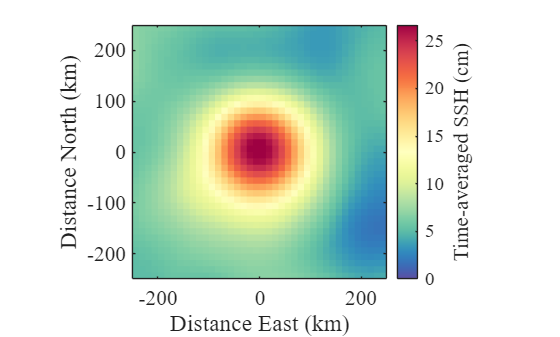

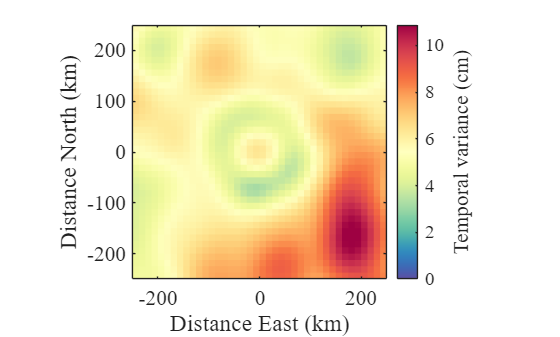

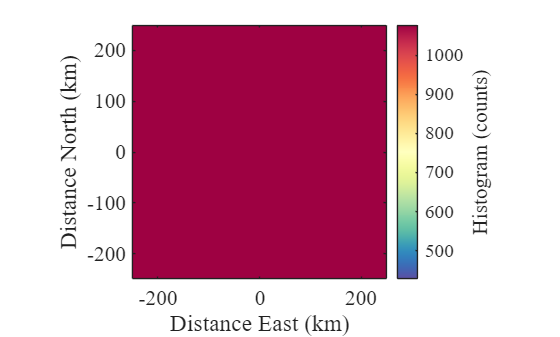

time_window=1:length(timeo)-1;
mapped_window.t=mapped_extracted.t(time_window);
mapped_window.x=mapped_extracted.x;
mapped_window.y=mapped_extracted.y;
mapped_window.ssh=mapped_extracted.ssh(:,:,time_window);

% time-averaged eddy composite
% [mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D_grid(mapped_window,eddyPath_fun_t);
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(mapped_window,eddyPath_fun_t);% options: bin_size=12.5*1e3

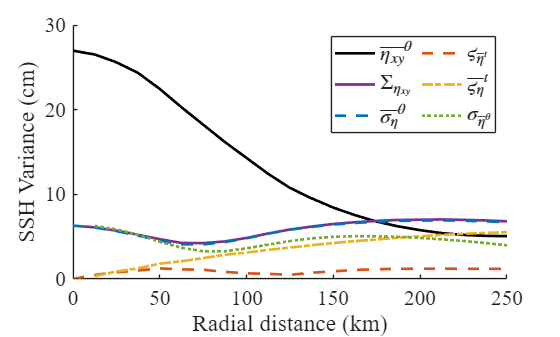

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(mapped_window,eddyPath_fun_t);

time_window=1:length(timeo)-1;
mapped_window.t=mapped_extracted.t(time_window);
mapped_window.x=mapped_extracted.x;
mapped_window.y=mapped_extracted.y;
mapped_window.ssh=mapped_extracted.ssh(:,:,time_window);

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(mapped_window,eddyPath_fun_t,"tbin_size",10); %mapped product are in the increments of days

## 5. Parameter extraction from mapped product

%%
% [center_zeta,amplitude,radius,core_zeta,shield_zeta] = findEddyCentroid(x, y, ssh,'BoundaryType','zero-zeta','lato',24,'GetBoundary', true,'epsilon',0.01);
amplitude = ncread(filename,'eddy/amplitude')*100;
radius = ncread(filename,'eddy/speed_radius')/1e3;

% Calculate grid spacing
dx = mapped_extracted.x(2) - mapped_extracted.x(1);
dy = mapped_extracted.y(2) - mapped_extracted.y(1);
% calculate zeta in (x,y,t) matrix
[zeta] = zetaField(dx,dy,mapped_extracted.ssh,lato=mean(eddyPath.lat));

[center_zeta,amplitude,radius,core_zeta,shield_zeta] = findEddyCentroid(mapped_window.x, mapped_window.y, mapped_window.ssh,'BoundaryType','zero-zeta','lato',24,'GetBoundary', true,'epsilon',0.01);

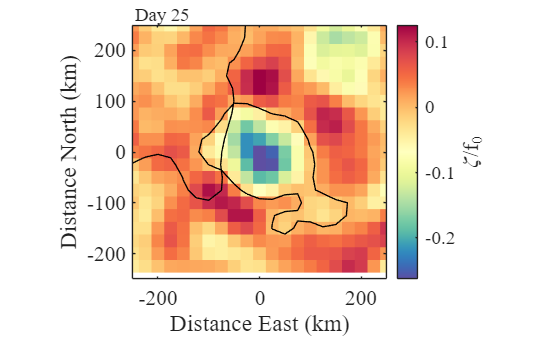

n=25;
zetaContours.core=core_zeta{n};
% zetaContours.shield=shield_zeta{n};
plotComposite(mapped_window.x,mapped_window.y,mapped_window.t(n),zeta(:,:,n),eddyPath_fun_t,contour=zetaContours)
hold on
text(-245,270,['Day ',num2str(n)],'FontSize',14,'FontName','times')

mapped_window.zeta = reshape(zeta,[],1);

[mz_zeta, rmid] = zetaProfile(mapped_window,eddyPath_fun_t);

Error using  : 
Colon operands must be real scalars.

Error in zetaProfile (line 31)
rbin = [-bin_size / 2:bin_size:max_r]';
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

## 5. Convergence Rate

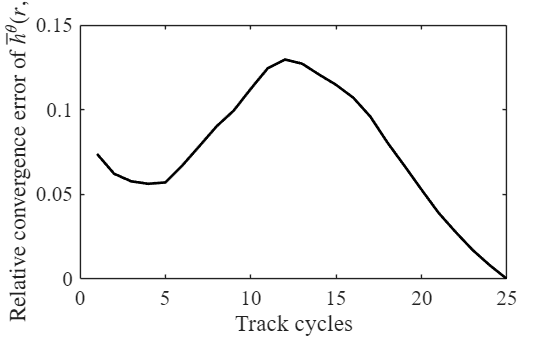

% how many cycles are needed to reach convergence to time-averaged profile
[convergence] = convergenceRate(mz_rt, numz_rt);

## 6. Gaussian fit

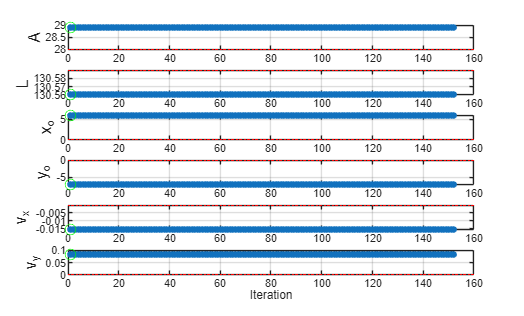

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 



    % mapped_field_extracted.ssh = ssh_interp;
    % mapped_field_extracted.x = xmid;
    % mapped_field_extracted.y = xmid;
    % mapped_field_extracted.t = timeo;
eddyFit_fun = @(x,y,t,A,L,x0,y0,cx,cy) A.*exp(-((x-x0-cx*t).^2 + (y-y0-cy*t).^2)/L^2);
[~,amplitude,radius] = findEddyCentroid(mapped_extracted.x, mapped_extracted.y, mapped_extracted.ssh,'thresholdratio',0.9,'GetBoundary', true);
eddyParams.A=amplitude;
eddyParams.L=radius;
eddyParams.xe=eddyPath_fun_t.xe;
eddyParams.ye=eddyPath_fun_t.ye;

trueParams.A=mean(eddyParams.A);
trueParams.L=mean(eddyParams.L);
trueParams.x0=eddyParams.xe(0);
trueParams.y0=eddyParams.ye(0);
trueParams.cx = mean(vdiff(eddyParams.xe(eddy_time),1));
trueParams.cy = mean(vdiff(eddyParams.ye(eddy_time),1));

% new inital parameters for this window
initParams.A = trueParams.A+2*(rand-0.5)*1e-2; %random uncertainty +/- 1e-2
initParams.L = trueParams.L+2*(rand-0.5)*1e3; %random uncertainty +/- 1e3
%assuming you roughly know the eddy center from eddy-tracking algorithm
%beginning of this particular window minus t0 offset of the entire eddy lifetime
% initParams_window.x0 = initParams.x0+i*initParams.cx*max(elapsed_time_window);
% initParams_window.y0 = initParams.y0+i*initParams.cy*max(elapsed_time_window);
initParams.x0 = trueParams.x0+2*(rand-0.5)*10e3; %random uncertainty +/- 10e3
initParams.y0 = trueParams.y0+2*(rand-0.5)*10e3;
initParams.cx = trueParams.cx+2*(rand-0.5)*1e2;  %random uncertainty +/- 1e2
initParams.cy = trueParams.cy+2*(rand-0.5)*1e2;


% initParams.A = true_params.A-0.
% initParams.L = true_params.L+5e3;
% initParams.x0 = true_params.x0-50e3;
% initParams.y0 = true_params.y0+50e3;
% initParams.cx = true_params.cx-0.2e3;
% initParams.cy = true_params.cy+0.2e3;

plot_func = @(xtrans, optimValues, state) plotParamsIteration_ref(xtrans, optimValues, state, [], trueParams);
it_options = optimset('OutputFcn', plot_func,'TolX',1e-3,'TolFun',1e-3);
paramsFit = FitAlongTrackXYToEddyModel(alongtrack, eddyFit_fun, initParams, it_options);

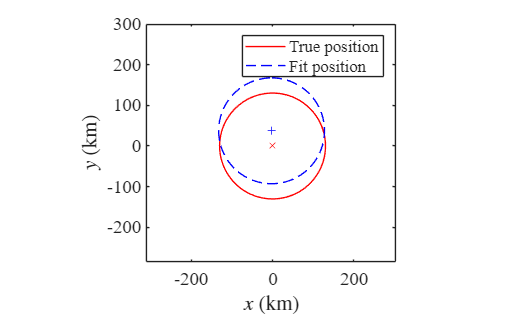

plotFitPosition(eddyPath_fun_t,paramsFit,trueParams)
xlim([min(x_km(:)),max(x_km(:))]);ylim([min(y_km(:)),max(y_km(:))])

%% time windowed fit
it_options = optimset('TolX',1e-3,'TolFun',1e-3);
[paramsCell, trueParamsCell, window_center] = FitAlongTrackXYToEddyModelWindowed(alongtrack, eddyFit_fun, eddyParams, it_options,"window",100);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         C

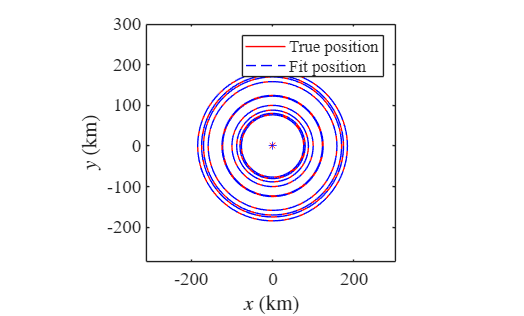

plotFitPosition(eddyPath_fun_t,paramsCell,trueParamsCell)
xlim([min(x_km(:)),max(x_km(:))]);ylim([min(y_km(:)),max(y_km(:))])

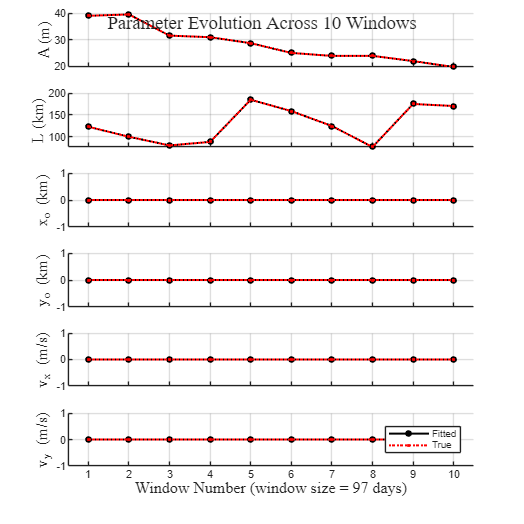

plotFitWindowed(paramsCell,trueParamsCell, eddyPath_fun_t)

% % To analyze a specific window in detail (e.g., window 3):
 plotSingleWindowFit(alongtrack, eddyPath_fun_t, paramsCell, trueParamsCell, 3);

